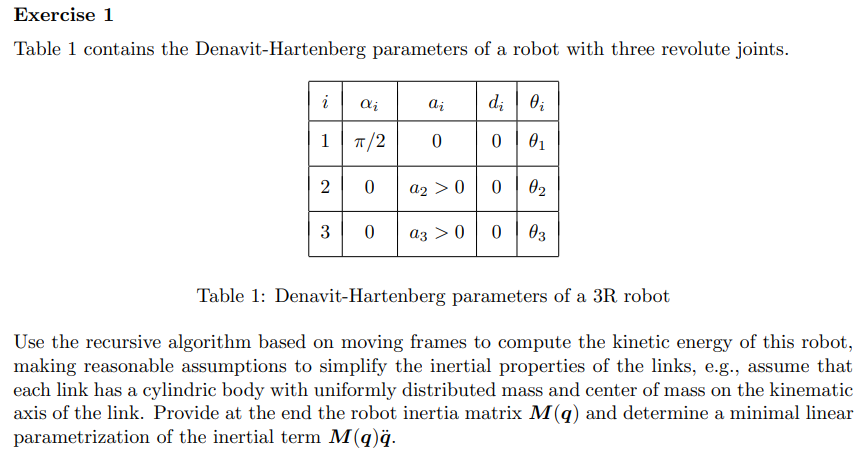

clear; clc;
syms theta_1 theta_2 theta_3 q_dot_1 q_dot_2 q_dot_3 real
syms a_2 a_3 m_1 m_2 m_3 r1x r2x r3x  q1 q2 q3 d_1 d_2 d_3 real

% Tipo di giunti (3 giunti rotazionali)
joint_types = 'rrr';

% Tabella DH [alpha, a, d, theta]
DH = [pi/2  0    0   q1;
       0    a_2  0   q2;
       0    a_3  0   q3];

% Vettori delle variabili generalizzate e delle loro derivate
q = [q1; q2; q3];
q_dot = [q_dot_1; q_dot_2; q_dot_3];

% Masse
m = [m_1; m_2; m_3];

% Inerzie baricentriche (3x1 perché si suppone momento solo attorno z)
syms I1z I1x I2z I2x I3z I3x I1y real
I1 = diag([I1x, I1y, I1x])

$$I1 = \left(\begin{array}{ccc} \mathrm{I1x} & 0 & 0\\ 0 & \mathrm{I1y} & 0\\ 0 & 0 & \mathrm{I1x} \end{array}\right)$$

I2 = diag([I2x, I2z, I2z]);
I3 = diag([I3x, I3z, I3z]);
I_ci = {I1, I2, I3}  % cell array 1x3, come richiesto dalla funzione

I_ci = 1×3 cell array
    {3×3 sym}    {3×3 sym}    {3×3 sym}



% Posizioni dei CoM nel proprio sistema di riferimento
rc = {[0; 0; 0], [d_2; 0; 0], [d_3; 0; 0]};


% Condizioni iniziali (base del robot)
v0 = [0; 0; 0];
omega0 = [0; 0; 0];

% Chiamata alla funzione principale
[T, Ti_array] = compute_kinetic_energy_T_Ti(joint_types, DH, q, q_dot, rc, m, [I_ci{:}], v0, omega0, true);

Link 1------------------------------------


$$omegai\_i = \left(\begin{array}{c} 0\\ {\dot{q}}_{1}\\ 0 \end{array}\right)$$

$$vi\_ci = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$vi\_i = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$Ti = \frac{\mathrm{I1x}\,{{\dot{q}}_{1}}^{2}}{2}$$


---------------------------------------------

Link 2------------------------------------


$$omegai\_i = \left(\begin{array}{c} {\dot{q}}_{1}\,\sin\left(q_{2}\right)\\ {\dot{q}}_{1}\,\cos\left(q_{2}\right)\\ {\dot{q}}_{2} \end{array}\right)$$

$$vi\_ci = \left(\begin{array}{c} 0\\ {\dot{q}}_{2}\,\left(a_{2}+d_{2}\right)\\ -{\dot{q}}_{1}\,\cos\left(q_{2}\right)\,\left(a_{2}+d_{2}\right) \end{array}\right)$$

$$vi\_i = \left(\begin{array}{c} 0\\ a_{2}\,{\dot{q}}_{2}\\ -a_{2}\,{\dot{q}}_{1}\,\cos\left(q_{2}\right) \end{array}\right)$$

$$Ti = \frac{m_{2}\,{\left(a_{2}+d_{2}\right)}^{2}\,\left({{\dot{q}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$


---------------------------------------------

Link 3------------------------------------


$$omegai\_i = \left(\begin{array}{c} {\dot{q}}_{1}\,\sin\left(q_{2}+q_{3}\right)\\ {\dot{q}}_{1}\,\cos\left(q_{2}+q_{3}\right)\\ {\dot{q}}_{2}+{\dot{q}}_{3} \end{array}\right)$$

$$vi\_ci = \left(\begin{array}{c} a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{3}\right)\\ d_{3}\,\left({\dot{q}}_{2}+{\dot{q}}_{3}\right)+a_{3}\,{\dot{q}}_{2}+a_{3}\,{\dot{q}}_{3}+a_{2}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)\\ -{\dot{q}}_{1}\,\left(a_{3}\,\cos\left(q_{2}+q_{3}\right)+d_{3}\,\cos\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\right) \end{array}\right)$$

$$vi\_i = \left(\begin{array}{c} a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{3}\right)\\ a_{3}\,{\dot{q}}_{2}+a_{3}\,{\dot{q}}_{3}+a_{2}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)\\ -a_{2}\,{\dot{q}}_{1}\,\cos\left(q_{2}\right)-a_{3}\,{\dot{q}}_{1}\,\cos\left(q_{2}+q_{3}\right) \end{array}\right)$$

$$Ti = \frac{m_{3}\,\left({\left(d_{3}\,\left({\dot{q}}_{2}+{\dot{q}}_{3}\right)+a_{3}\,{\dot{q}}_{2}+a_{3}\,{\dot{q}}_{3}+a_{2}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)\right)}^{2}+{{\dot{q}}_{1}}^{2}\,{\left(a_{3}\,\cos\left(q_{2}+q_{3}\right)+d_{3}\,\cos\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\right)}^{2}+{a_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\,{\sin\left(q_{3}\right)}^{2}\right)}{2}$$


---------------------------------------------




% Stampa finale
disp("Energia cinetica totale T:");

Energia cinetica totale T:


disp(simplify(T));

$$\frac{\mathrm{I1x}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{3}\,\left({\left(d_{3}\,\left({\dot{q}}_{2}+{\dot{q}}_{3}\right)+a_{3}\,{\dot{q}}_{2}+a_{3}\,{\dot{q}}_{3}+a_{2}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)\right)}^{2}+{{\dot{q}}_{1}}^{2}\,{\left(a_{3}\,\cos\left(q_{2}+q_{3}\right)+d_{3}\,\cos\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\right)}^{2}+{a_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\,{\sin\left(q_{3}\right)}^{2}\right)}{2}+\frac{m_{2}\,{\left(a_{2}+d_{2}\right)}^{2}\,\left({{\dot{q}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$

disp("Energie cinetiche parziali Ti:");

Energie cinetiche parziali Ti:


for i = 1:length(Ti_array)
    fprintf("T_%d = \n", i);
    disp(simplify(Ti_array(i)));
end

T_1 = 


$$\frac{\mathrm{I1x}\,{{\dot{q}}_{1}}^{2}}{2}$$

T_2 = 


$$\frac{m_{2}\,{\left(a_{2}+d_{2}\right)}^{2}\,\left({{\dot{q}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$

T_3 = 


$$\frac{m_{3}\,\left({\left(d_{3}\,\left({\dot{q}}_{2}+{\dot{q}}_{3}\right)+a_{3}\,{\dot{q}}_{2}+a_{3}\,{\dot{q}}_{3}+a_{2}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)\right)}^{2}+{{\dot{q}}_{1}}^{2}\,{\left(a_{3}\,\cos\left(q_{2}+q_{3}\right)+d_{3}\,\cos\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\right)}^{2}+{a_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\,{\sin\left(q_{3}\right)}^{2}\right)}{2}$$



% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);
M13 = diff(diff(T, q_dot_1), q_dot_3);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);
M23 = diff(diff(T, q_dot_2), q_dot_3);

M31 = diff(diff(T, q_dot_3), q_dot_1);
M32 = diff(diff(T, q_dot_3), q_dot_2);
M33 = diff(diff(T, q_dot_3), q_dot_3);

M = [M11, M12, M13; M21, M22, M23; M31, M32, M33]

$$M = \begin{array}{l} \left(\begin{array}{ccc} \mathrm{I1x}+m_{3}\,{\left(a_{3}\,\cos\left(q_{2}+q_{3}\right)+d_{3}\,\cos\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\right)}^{2}+m_{2}\,{\cos\left(q_{2}\right)}^{2}\,{\left(a_{2}+d_{2}\right)}^{2} & 0 & 0\\ 0 & \frac{m_{3}\,\left(2\,{\sigma_{2}}^{2}+2\,{a_{2}}^{2}\,{\sin\left(q_{3}\right)}^{2}\right)}{2}+m_{2}\,{\left(a_{2}+d_{2}\right)}^{2} & \sigma_{1}\\ 0 & \sigma_{1} & m_{3}\,{\left(a_{3}+d_{3}\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{3}\,\left(a_{3}+d_{3}\right)\,\sigma_{2}\\ \sigma_{2}=a_{3}+d_{3}+a_{2}\,\cos\left(q_{3}\right) \end{array}$$

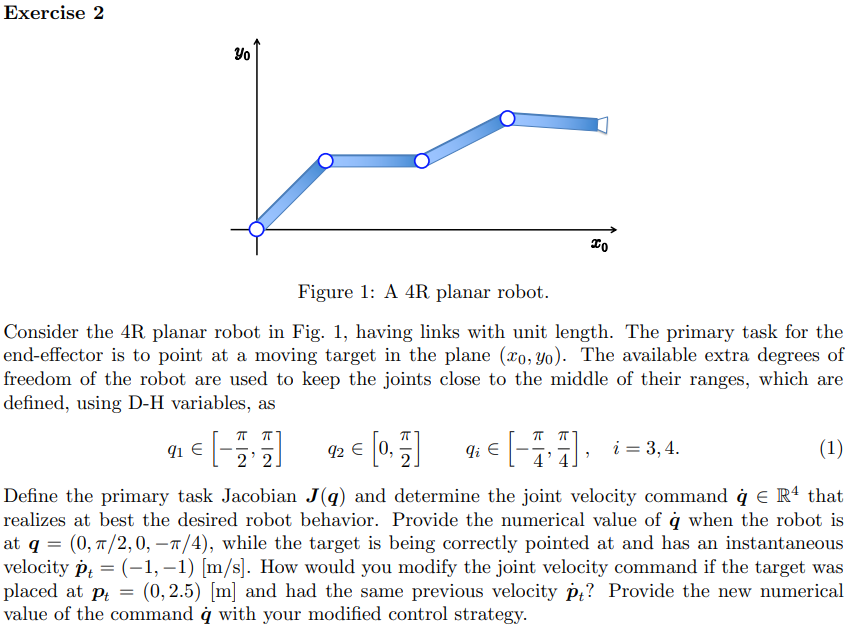

syms q1 q2 q3 q4

p = [cos(q1)+cos(q1+q2)+cos(q1+q2+q3)+cos(q1+q2+q3+q4);
     sin(q1)+sin(q1+q2)+sin(q1+q2+q3)+sin(q1+q2+q3+q4);];
J = jacobian(p,[q1,q2,q3,q4]);
J_subs = eval(subs(J,[q1,q2,q3,q4],[0,pi/2,0,-pi/4]))

J_subs =    -2.7071   -2.7071   -1.7071   -0.7071
    1.7071    0.7071    0.7071    0.7071


p_dot = [-1;-1;]

p_dot =     -1
    -1


q_dot = pinv(J_subs)*p_dot

q_dot =    -0.9010
    1.3237
    0.2536
   -0.8164


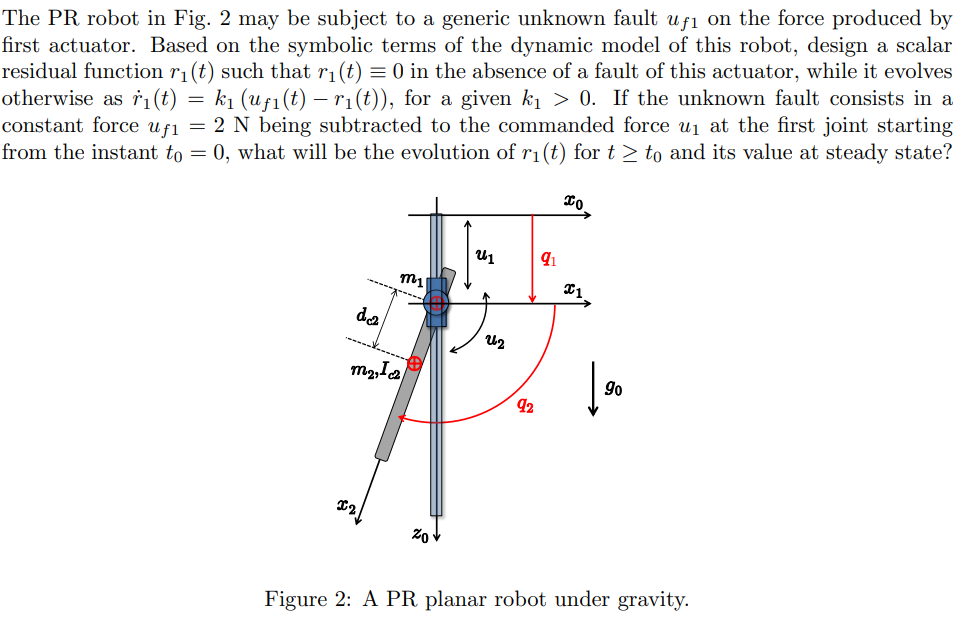

#### Utils function

function translation = affine_get_translation(T)
    translation = [T(1, 4); T(2, 4); T(3, 4)];
end
function R = affine_get_R(T)
    R = T(1:3, 1:3);
end
function T = konig_theorem(m_i, vi_ci, omegai_i, Ii_ci)
    m = m_i;
    vc = vi_ci;
    omega = omegai_i;
    Ic = Ii_ci;
    
    vc_squared = (vc')*vc;
    
    if class(vc_squared) ~= "double"
        vc_squared = simplify(vc_squared);
    end
    
    T = 0.5*m*vc_squared + 0.5*(omega')*Ic*omega;
    T = simplify(T);
end
function R = get_rotation_mat(A)
    R = A(1:3, 1:3);
end

function [omegai_i, vi_ci, vi_i] = compute_omega_vc_v(ri_ci, rh_i, Rh_i, qi_dot, omegah_h, vh_h, is_prismatic)
    if is_prismatic
        sigma = 1;
    else
        sigma = 0;
    end
    
    Ri_h = Rh_i';
    zh_h = [0 0 1]';
    omegai_i = simplify(Ri_h*(omegah_h + (1-sigma)*qi_dot*zh_h));
    
        
    vi_i = simplify(Ri_h*(vh_h + sigma*qi_dot*zh_h) + cross(omegai_i, Ri_h*rh_i));
    vi_ci = simplify(vi_i + cross(omegai_i, ri_ci));

end

function [T, A] = DHMatrix(arrays)
% T = DHMatrix(arrays) takes as inputs:
%   -arrays: a n-vector of vectors composed like this: [alpha a d theta]
% and outputs:
%   -T: the product of all the matrices corresponding to each vector of arrays
% Remember that:
% cos(q1 + q2) = cos(q1)*cos(q2) - sin(q1)*sin(q2)
% sin(q1 + q2) = cos(q1)*sin(q2) + cos(q2)*sin(q1)
% making use of the simplify function these are converted automatically

    T = eye(4);
    nums = size(arrays);
    
    A = cell(1,nums(1));
    
    for i = 1:nums(1)
        line = arrays(i, :);
        R = [cos(line(4)) -cos(line(1))*sin(line(4)) sin(line(1))*sin(line(4)) line(2)*cos(line(4));
             sin(line(4)) cos(line(1))*cos(line(4)) -sin(line(1))*cos(line(4)) line(2)*sin(line(4));
             0 sin(line(1)) cos(line(1)) line(3);
             0 0 0 1;];
        A{i} = R;
        T = T * R;   
    end

    if isa(T, 'sym')
        T = simplify(T);
    end
end

function [T, array_Ti] = compute_kinetic_energy_T_Ti(string_joints_types, dhtable, array_q, array_q_dot, cell_ri_ci, array_m_i, array_I_ci, v0_0, omega0_0, print_info)
    T = 0;
    n = length(array_q);
    types = lower(string_joints_types);
    types = char(types);
    
    omegah_h = omega0_0;
    vh_h = v0_0;
    
    array_Ti = sym([]);
    
    [T_mat, A] = DHMatrix(dhtable);
    for i=1:n
        if types(i) == 'r'
            is_prismatic = false;
        elseif types(i) == 'p'
            is_prismatic = true;
        else
            fprintf("\nERROR\n");
        end
        
        ri_ci = cell_ri_ci{i};
        
        Ah_i = A{i};
        rh_i = affine_get_translation(Ah_i);
        Rh_i = affine_get_R(Ah_i);
        
        dq = array_q_dot(i);
        Ici_zz = array_I_ci(i);
        m_i = array_m_i(i);
        
        %link i
        [omegai_i, vi_ci, vi_i] = compute_omega_vc_v(ri_ci, rh_i, Rh_i, dq, omegah_h, vh_h, is_prismatic);
        omegai_i = simplify(omegai_i);
        vi_ci = simplify(vi_ci);
        vi_i = simplify(vi_i);
        
        Ti = simplify(konig_theorem(m_i, vi_ci, omegai_i, Ici_zz));
        array_Ti = [array_Ti, Ti];
        T = T + Ti;

        if print_info
            fprintf("Link %d------------------------------------\n", i);
            display(omegai_i);
            display(vi_ci);
            display(vi_i);
            display(Ti);
            fprintf("\n---------------------------------------------\n\n");
        end
        
        omegah_h = omegai_i;
        vh_h = vi_i;
    end
    
end
